# A test harness script - **stencils**

Create Thermal and Geometry parameters

OBJ_params = bh_sys_params_CLS("bh_PARAMS_DATABASE.xlsx", "SET_1");

OBJ_params.Delta_X = 0.001; 
OBJ_params.Delta_Y = 0.001; 

## Test the [bh_get_node_stencils](matlab:  edit bh_get_node_stencils) function

Compute a table of the Thermal stencils for our different NODE Types

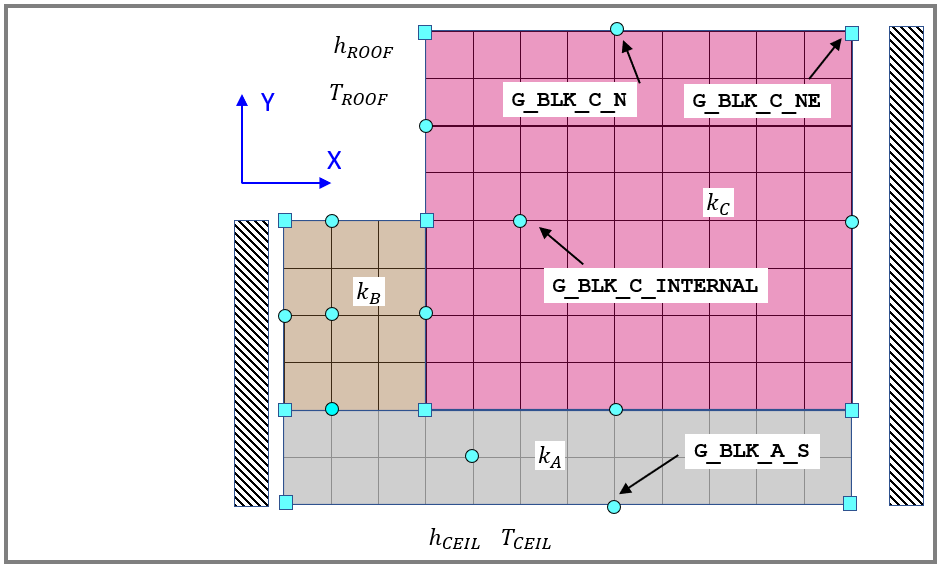

**ATTENTION:**  will take approx 1 minute to compute

sten_TAB = bh_get_node_stencils(OBJ_params)


 ... Finished [ 1] of 23 :  NODE_TYPE = G_BLK_B_INTERNAL
 ... Finished [ 2] of 23 :  NODE_TYPE = G_BLK_B_NW
 ... Finished [ 3] of 23 :  NODE_TYPE = G_BLK_B_N
 ... Finished [ 4] of 23 :  NODE_TYPE = G_BLK_B_NE
 ... Finished [ 5] of 23 :  NODE_TYPE = G_BLK_B_E
 ... Finished [ 6] of 23 :  NODE_TYPE = G_BLK_B_SE
 ... Finished [ 7] of 23 :  NODE_TYPE = G_BLK_B_S
 ... Finished [ 8] of 23 :  NODE_TYPE = G_BLK_B_SW
 ... Finished [ 9] of 23 :  NODE_TYPE = G_BLK_B_W
 ... Finished [10] of 23 :  NODE_TYPE = G_BLK_C_INTERNAL
 ... Finished [11] of 23 :  NODE_TYPE = G_BLK_C_W
 ... Finished [12] of 23 :  NODE_TYPE = G_BLK_C_NW
 ... Finished [13] of 23 :  NODE_TYPE = G_BLK_C_N
 ... Finished [14] of 23 :  NODE_TYPE = G_BLK_C_NE
 ... Finished [15] of 23 :  NODE_TYPE = G_BLK_C_E
 ... Finished [16] of 23 :  NODE_TYPE = G_BLK_C_SE
 ... Finished [17] of 23 :  NODE_TYPE = G_BLK_C_S
 ... Finished [18] of 23 :  NODE_TYPE = G_BLK_A_INTERNAL
 ... Finished [19] of 23 :  NODE_TYPE = G_BLK_A_SW
 ... Finished [20] o

sten_TAB = 23×15 table
                           node_type_fd                                                                                                                                      s_A                                                                                                                                                              s_b                                                                                  s_x                                                                                                                  str_x                                                               T_mM1_nP1     T_m_nP1     T_mP1_nP1     T_mM1_n      T_m_n      T_mP1_n     T_mM1_nM1     T_m_nM1     T_mP1_nM1     b 

## Test the [bh_fd_stencil_CLS](matlab: edit bh_fd_stencil_CLS) class

**ATTENTION:**  will take approx 1 minute to compute

OBJ_fd_stencils = bh_fd_stencil_CLS(OBJ_params)


 ... Finished [ 1] of 23 :  NODE_TYPE = G_BLK_B_INTERNAL
 ... Finished [ 2] of 23 :  NODE_TYPE = G_BLK_B_NW
 ... Finished [ 3] of 23 :  NODE_TYPE = G_BLK_B_N
 ... Finished [ 4] of 23 :  NODE_TYPE = G_BLK_B_NE
 ... Finished [ 5] of 23 :  NODE_TYPE = G_BLK_B_E
 ... Finished [ 6] of 23 :  NODE_TYPE = G_BLK_B_SE
 ... Finished [ 7] of 23 :  NODE_TYPE = G_BLK_B_S
 ... Finished [ 8] of 23 :  NODE_TYPE = G_BLK_B_SW
 ... Finished [ 9] of 23 :  NODE_TYPE = G_BLK_B_W
 ... Finished [10] of 23 :  NODE_TYPE = G_BLK_C_INTERNAL
 ... Finished [11] of 23 :  NODE_TYPE = G_BLK_C_W
 ... Finished [12] of 23 :  NODE_TYPE = G_BLK_C_NW
 ... Finished [13] of 23 :  NODE_TYPE = G_BLK_C_N
 ... Finished [14] of 23 :  NODE_TYPE = G_BLK_C_NE
 ... Finished [15] of 23 :  NODE_TYPE = G_BLK_C_E
 ... Finished [16] of 23 :  NODE_TYPE = G_BLK_C_SE
 ... Finished [17] of 23 :  NODE_TYPE = G_BLK_C_S
 ... Finished [18] of 23 :  NODE_TYPE = G_BLK_A_INTERNAL
 ... Finished [19] of 23 :  NODE_TYPE = G_BLK_A_SW
 ... Finished [20] o

OBJ_fd_stencils =   bh_fd_stencil_CLS with properties:

    tab: [23×15 table]


The main data component for this is the table:

OBJ_fd_stencils.tab

ans = 23×15 table
                           node_type_fd                                                                                                                                      s_A                                                                                                                                                              s_b                                                                                  s_x                                                                                                                  str_x                                                               T_mM1_nP1     T_m_nP1     T_mP1_nP1     T_mM1_n      T_m_n      T_mP1_n     T_mM1_nM1     T_m_nM1     T_mP1_nM1     b  
   

**Inspect one of the node type  stencils**

node_type = bh_fd_node_type_ENUM.G_BLK_B_INTERNAL;

OBJ_fd_stencils.show( node_type , "symbolic")


 ------------------------------ 
 *** SYMBOLIC *** A.x = b
 --->  x 

$$ans = \left(\begin{array}{ccccccccc} T_{\mathrm{mM1},\mathrm{nP1}} & T_{m,\mathrm{nP1}} & T_{\mathrm{mP1},\mathrm{nP1}} & T_{\mathrm{mM1},n} & T_{m,n} & T_{\mathrm{mP1},n} & T_{\mathrm{mM1},\mathrm{nM1}} & T_{m,\mathrm{nM1}} & T_{\mathrm{mP1},\mathrm{nM1}} \end{array}\right)$$


 --->  A 

$$ans = \left(\begin{array}{ccccccccc} 0 & 0 & 0 & -\frac{\Delta_{Y}\,k_{B}}{2\,\Delta_{X}} & \Delta_{X}\,h_{\mathrm{ROOF}}+\frac{\Delta_{X}\,k_{B}}{\Delta_{Y}}+\frac{\Delta_{Y}\,k_{B}}{\Delta_{X}} & -\frac{\Delta_{Y}\,k_{B}}{2\,\Delta_{X}} & 0 & -\frac{\Delta_{X}\,k_{B}}{\Delta_{Y}} & 0 \end{array}\right)$$


 --->  b 

$$ans = \left(\begin{array}{c} \Delta_{X}\,T_{\mathrm{ROOF}}\,h_{\mathrm{ROOF}} \end{array}\right)$$

You can retrieve the SPECIFC stencil for a node

[A, b, x_str] = OBJ_fd_stencils.retrieve_Abx( string(node_type),  1,  2)

A =    -0.0600    0.2440   -0.0600   -0.1200


b = 0.2200

x_str = 1×4 string array
    "T_0_2"    "T_1_2"    "T_2_2"    "T_1_1"
